# **Numerical Interpolation **

**Numerical Programming**

**mod: 2022.9.27**

## Problem 

An experiment is conducted that measures the pressure of a gas by heating it in a closed chamber. 

- Predict the pressure at T=100C

- Estimate  interpolated value P when T=75

close 
clear all

T=[0 10 20 30 40 50 60 70 80];
P=[0.94 0.96 1 1.05 1.07 1.09 1.14 1.17 1.21];
n=length(T);

### P1. (Curve Fitting) 

#### Predict the pressure if the temperature is increased to 150C.

Based on Charles's law for ideal gas  P=kT, where k is a constant.

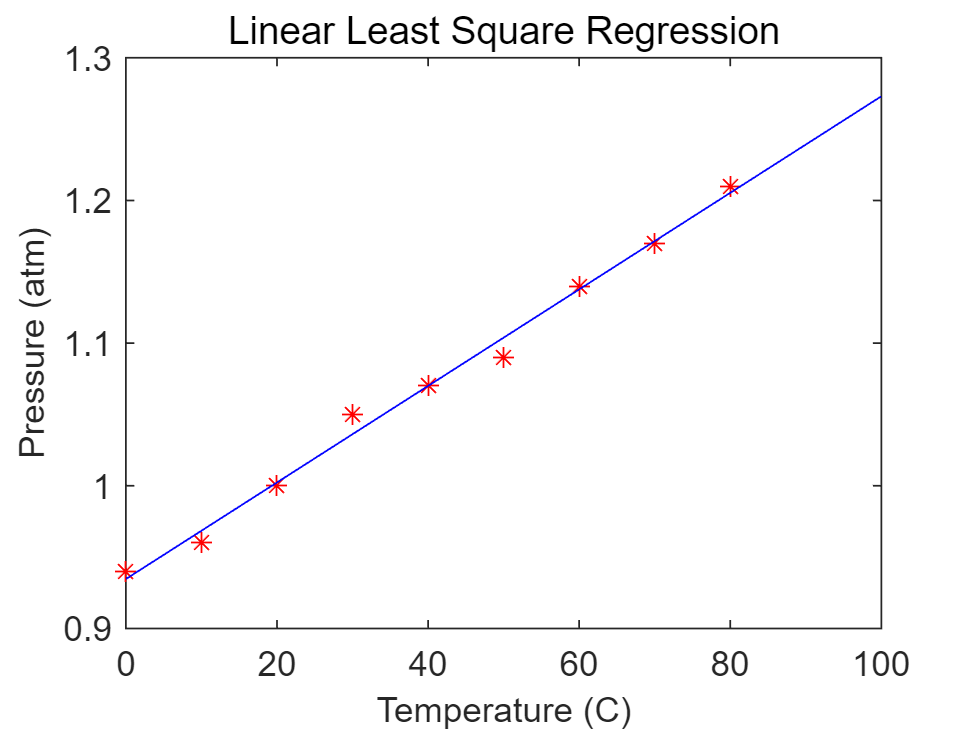

% Polyfit
X=T;
Y=P;

Z=polyfit(X,Y,1); % Curve Fit MATLAB function

t=0:10:100;
Yhat=Z(2)+Z(1).*t;

figure
plot(X,Y, '*r')
hold on
plot(t,Yhat, '-b')
xlabel('Temperature (C)','fontsize',10)
ylabel('Pressure (atm)','fontsize',10)    
title('Linear Least Square Regression');
xlim([0.0 100.0])

### P2. (Interpolation) 

#### **Estimate interpolated value P when T=75C**

Using a linear interpolation

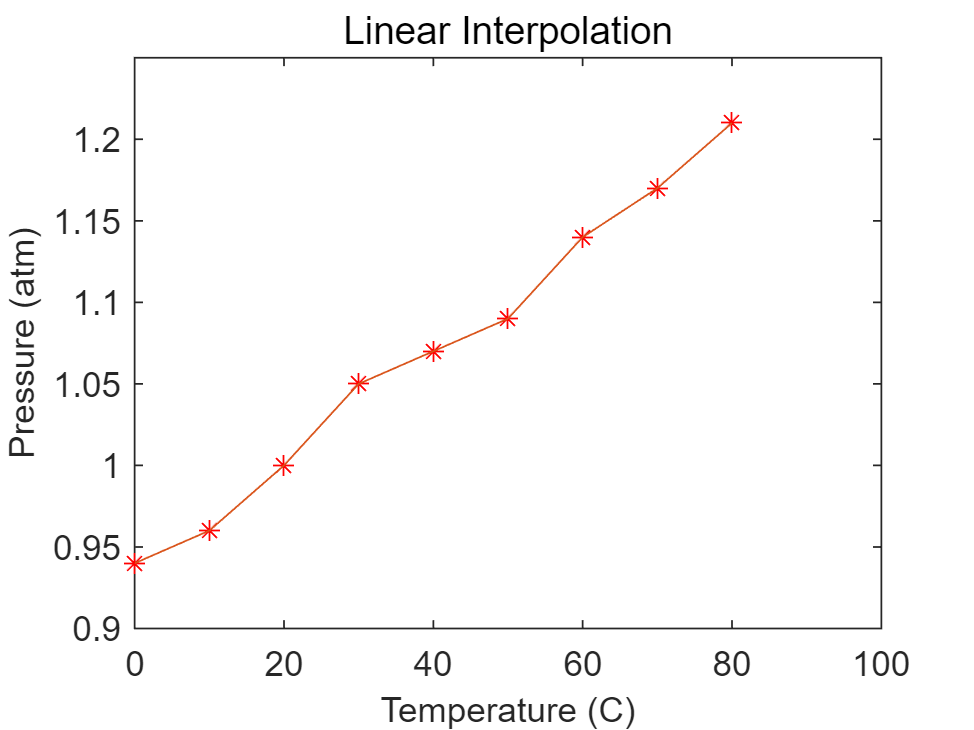

figure
Yin1 = interp1(X,Y,X,'linear');
plot(X,Y,'*r',X,Yin1);
xlabel('Temperature (C)','fontsize',10)
ylabel('Pressure (atm)','fontsize',10)    
title('Linear Interpolation');
xlim([0.0 100.0])

Using a spline cubic interpolation

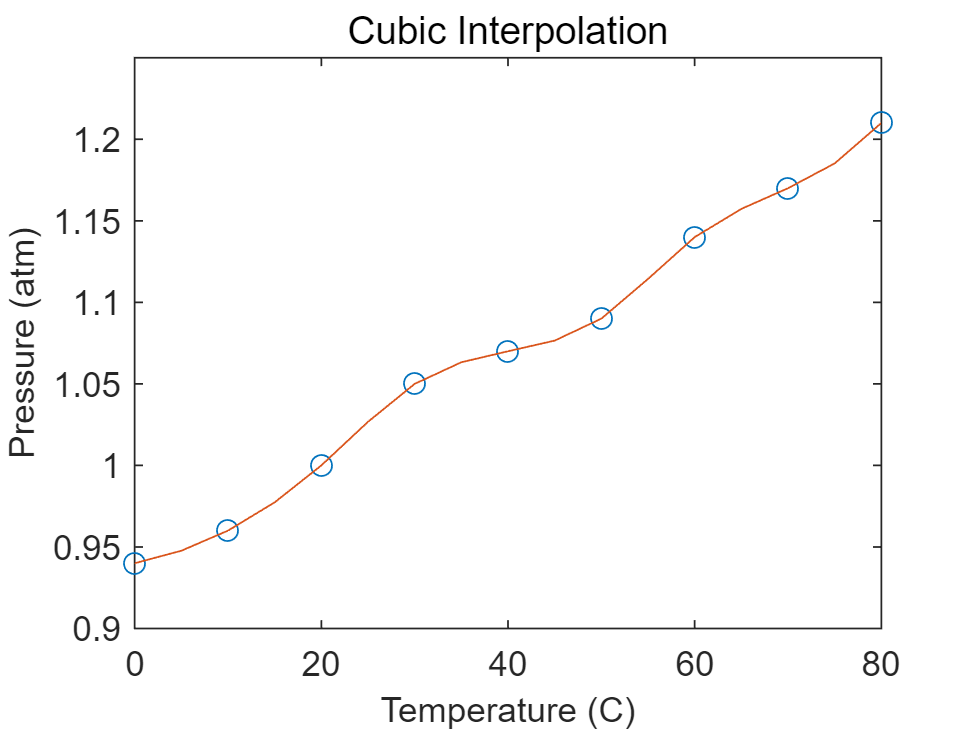

% Interpolation-cubic
figure
Xin=0:5:80;
Yin = interp1(X,Y,Xin,'spline');
plot(X,Y,'o',Xin,Yin);
xlabel('Temperature (C)','fontsize',10)
ylabel('Pressure (atm)','fontsize',10)    
title('Cubic Interpolation');